# Aircraft Pitch: System Modeling

MMAE 443 Systems Analysis and Control

Zain Baig, Caden Gigstad, Mauricio Verduzco Chavira

## About the Model:

### **Model Description and Assumptions**

In this example we are designing an autopilot controller for one of Boeing's commercial aircraft. Assumptions are:

- Steady cruise in constant altitude and velocity

- Thrust, drag, weight and lift balance each other out.

- Change in pitch angle will not change the speed of the aircraft

The model is linearized and only analyzes the longitudinal perspective.

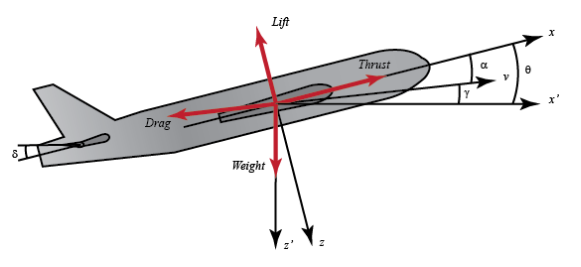

### **Mathematical Modeling**

#### **Equations of Motion**


$$\dot{\alpha \;} =\mu \Omega \sigma \left\lbrack -\left(C_L +C_D \right)\alpha +\frac{1}{\left(\mu -C_L \right)}q-\left(C_W \sin \gamma \right)\theta +C_L \right\rbrack$$



$$\dot{q} =\frac{\mu \Omega }{2i_{\textrm{yy}} }\left\lbrack \left\lbrack C_M -\eta \left(C_L +C_D \right)\right\rbrack \alpha +\left\lbrack C_M +\sigma C_M \left(1-\mu C_L \right)\right\rbrack q+\left(\eta C_W \sin \gamma \right)\delta \right\rbrack$$



$$\dot{\theta} =\Omega q$$


#### **Plugging in some values**

For this system, the output will be the pitch angle $\theta$, and the input the elevator angle $\delta$. The rest of the variables are explained at the bottom of the document. For simplicity, the values provided by University of Michigan Control Tutorials were used for Matlab and Simulink. As numerical values are added, the following is obtained:


$$\dot{\alpha \;} =-0\ldotp 313\alpha \alpha +56\ldotp 7q+0\ldotp 232\delta$$



$$\dot{q} =-0\ldotp 0139\alpha -0\ldotp 426q+0\ldotp 0203\delta$$



$$\dot{\theta} =56\ldotp 7q$$


#### **Laplace Transform**

Perform Laplace Transform of these equations to obtain:


$$\textrm{sA}\left(s\right)=-0\ldotp 313A\left(s\right)+56\ldotp 7Q\left(s\right)+0\ldotp 232\Delta \left(s\right)$$



$$\textrm{sQ}\left(s\right)=-0\ldotp 0139A\left(s\right)-0\ldotp 426Q\left(s\right)+0\ldotp 0203\Delta \left(s\right)$$



$$s\Theta \left(s\right)=56\ldotp 7Q\left(s\right)$$


#### Transfer Function

After some more algebra we obtain the transfer function:


$$G\left(s\right)=\frac{\Theta \left(s\right)}{\Delta \left(s\right)}=\frac{1\ldotp 151s+0\ldotp 1774}{s^3 +0\ldotp {739}^2 +0\ldotp 921s}$$


The specific algebraic steps and substitutions can be consulted at the end of the document.

## **Analysis of step response for plant**

### **Step Response**

And we study the step response

num = [1.151 0.1774];
den = [1 0.739 0.921 0];
G = tf(num, den)

G =
 
      1.151 s + 0.1774
  -------------------------
  s^3 + 0.739 s^2 + 0.921 s
 
Continuous-time transfer function.
Model Properties


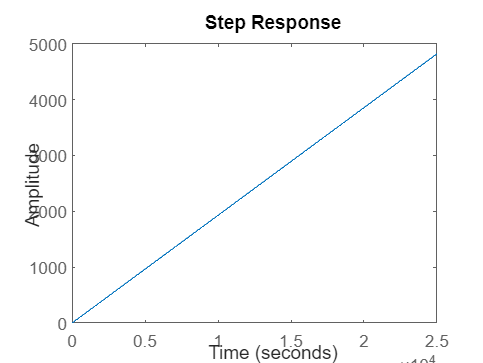

step(G)

It is evident that the system is not stable. This is because one of the poles of the transfer function will be zero. This means that the best possible result is a marginally stable system. 

### **Stability Analysis**

The following shows the location of the poles. 

poles = roots(den)

poles =    0.0000 + 0.0000i
  -0.3695 + 0.8857i
  -0.3695 - 0.8857i


And graphically:

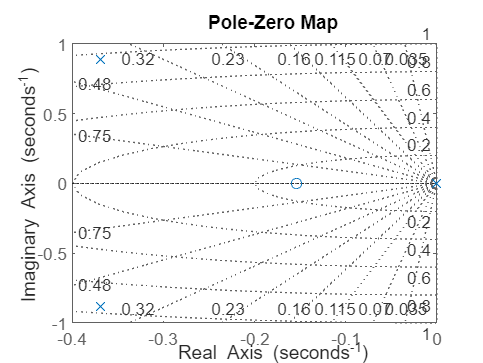

pzplot(G)
grid on

#### **Results**

The model cannot have static gain nor overshoot because of the instability of the system. Even if the values of the original variables were changed, the shape of the denominator polynomial 


$$s^{3\;} +{a*s}^2 +b*s=0$$


Will always yield a pole equal to zero as a common *s* can be factored out. 

## **Performance Requirements**

For a step reference of 0.2 radians (everything up to 1 unit)


$$t_{\textrm{ss}} \le 10$$



$$%O\ldotp S\ldotp \le 10%$$



$${\textrm{ss}}_e \le 2%$$


## **Feedback**

### **Original System**

We had the original system given by:

num = [1.151 0.1774];
den = [1 0.739 0.921 0];
G = tf(num,den)

G =
 
      1.151 s + 0.1774
  -------------------------
  s^3 + 0.739 s^2 + 0.921 s
 
Continuous-time transfer function.
Model Properties


### **Feedback Equation Modeling**

If feedback is added as follows: 

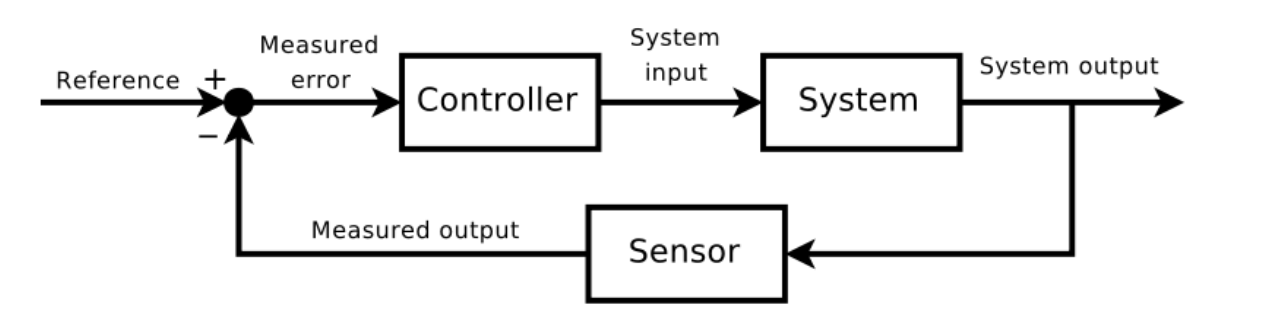

We get a new ecuation given by. 


$$Y\left(s\right)=\frac{G\left(s\right)}{1+G\left(s\right)H\left(s\right)}$$


Where Y is the output, G is the original plant and H is the sensor. 

### Sensor Transfer Function

syms s H
G = vpa((1.151*s + 0.1774)/(s^3 + 0.739*s^2 + 0.921*s),4);
Ysym = vpa(simplify(G/(1+G*H)),5)

$$Ysym = \frac{1.151e+33\,s+1.774e+32}{1.774e+32\,H+9.21e+32\,s+1.151e+33\,H\,s+7.39e+32\,s^{2}+1.0e+33\,s^{3}}$$

### Perfect Sensor

In this case, a perfect sensor is considered, meaning H = 1 and that there is no proportional constant. 

syms s
H = 1;
G = vpa((1.151*s + 0.1774)/(s^3 + 0.739*s^2 + 0.921*s),4);

#### Perfect Sensor - Transfer Function

Ysym = vpa(simplify(G/(1+G*H)),5)

$$Ysym = \frac{1.151e+33\,s+1.774e+32}{1.0e+33\,s^{3}+7.39e+32\,s^{2}+2.072e+33\,s+1.774e+32}$$

[num2, den2] = numden(Ysym);
Y= tf(sym2poly(num2),sym2poly(den2));

#### Perfect Sensor - Step Response

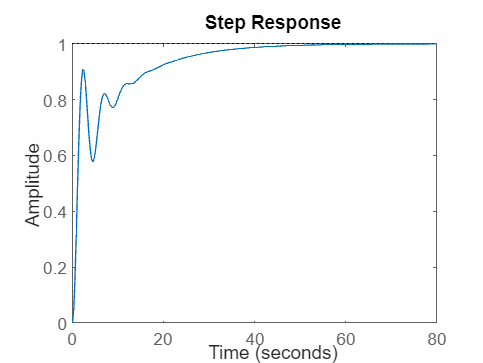

step(Y)

#### Perfect Sensor - Step Information Analysis

A stable system is now obtained. Unfortunately, the system has a lot of oscillation and long settling time. 

stepinfo(Y)

ans = struct with fields:
         RiseTime: 1.7882
    TransientTime: 35.0896
     SettlingTime: 35.0896
      SettlingMin: 0.5777
      SettlingMax: 0.9998
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9998
         PeakTime: 90.2716


### Non-Perfect Sensor

A non-perfect sensor in most systems is defined as


$$H\left(s\right)=\frac{K_h }{\tau *s+1}$$


Where Kh is an adjustable constant, and $\tau$ is a time delay constant for the sensor.

#### Non-Perfect Sensor Transfer Function

Utilizing the original plant and a delay of 0.5, the following transfer function is obtained:

syms s
G = vpa((1.151*s + 0.1774)/(s^3 + 0.739*s^2 + 0.921*s),4);
tau = 0.5;
H = 1/(tau*s+1); 
Ysym = vpa(simplify(G/(1+G*H)),5)

$$Ysym = \frac{1.151e+33\,s^{2}+2.4794e+33\,s+3.548e+32}{1.0e+33\,s^{4}+2.739e+33\,s^{3}+2.399e+33\,s^{2}+4.144e+33\,s+3.548e+32}$$

[num2, den2] = numden(Ysym);
Y= tf(sym2poly(num2),sym2poly(den2));

#### Non-Perfect Sensor Step Response

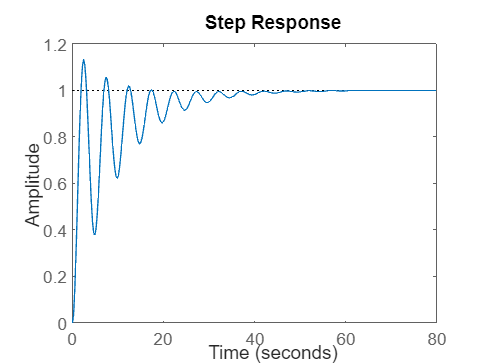

step(Y)

#### Non-Perfect Sensor Step Information Analysis

stepinfo(Y)

ans = struct with fields:
         RiseTime: 1.2679
    TransientTime: 35.6863
     SettlingTime: 35.6863
      SettlingMin: 0.3773
      SettlingMax: 1.1320
        Overshoot: 13.1989
       Undershoot: 0
             Peak: 1.1320
         PeakTime: 2.4636


#### Results

As can be seen in the step response, the system response is not satisfactory. There are many oscillations and a long settling time. This means further control must be added to gain a better system response.

#### The impact of different Tau configuration values in the performance

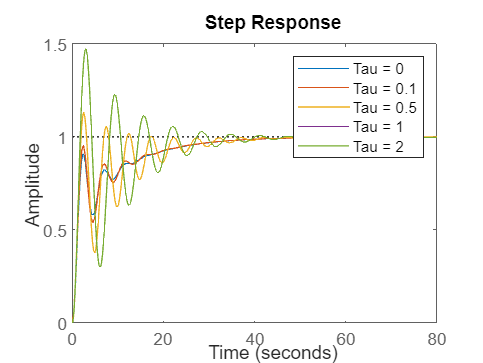

syms s
G = vpa((1.151*s + 0.1774)/(s^3 + 0.739*s^2 + 0.921*s),4);
tau = 0.0;
H = 1/(tau*s+1); 
Ysym = vpa(simplify(G/(1+G*H)),5);
[num2, den2] = numden(Ysym);
Y= tf(sym2poly(num2),sym2poly(den2));
step(Y)
hold on

G = vpa((1.151*s + 0.1774)/(s^3 + 0.739*s^2 + 0.921*s),4);
tau = 0.1;
H = 1/(tau*s+1); 
Ysym = vpa(simplify(G/(1+G*H)),5);
[num2, den2] = numden(Ysym);
Y= tf(sym2poly(num2),sym2poly(den2));
step(Y)

G = vpa((1.151*s + 0.1774)/(s^3 + 0.739*s^2 + 0.921*s),4);
tau = 0.5;
H = 1/(tau*s+1); 
Ysym = vpa(simplify(G/(1+G*H)),5);
[num2, den2] = numden(Ysym);
Y= tf(sym2poly(num2),sym2poly(den2));
step(Y)

G = vpa((1.151*s + 0.1774)/(s^3 + 0.739*s^2 + 0.921*s),4);
tau = 2;
H = 1/(tau*s+1); 
Ysym = vpa(simplify(G/(1+G*H)),5);
[num2, den2] = numden(Ysym);
Y= tf(sym2poly(num2),sym2poly(den2));
step(Y)

G = vpa((1.151*s + 0.1774)/(s^3 + 0.739*s^2 + 0.921*s),4);
tau = 2;
H = 1/(tau*s+1); 
Ysym = vpa(simplify(G/(1+G*H)),5);
[num2, den2] = numden(Ysym);
Y= tf(sym2poly(num2),sym2poly(den2));
step(Y)
hold off
legend('Tau = 0','Tau = 0.1','Tau = 0.5','Tau = 1','Tau = 2')

Observing various time constant values, the best possible result is given by = 0. However, there is no real sensor that gives a response with zero delay. Doing some research, it was learned that most gyro sensors take about 1000 samples per second, meaning that the time delay of a gyro sensor is about 0.001.

#### Final Configuration for Feedback

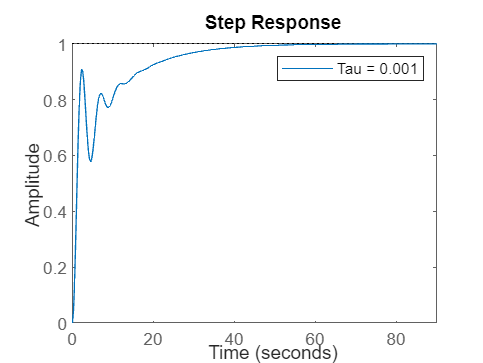

syms s
G = vpa((1.151*s + 0.1774)/(s^3 + 0.739*s^2 + 0.921*s),4);
tau = 0.001;
H = 1/(tau*s+1); 
Ysym = vpa(simplify(G/(1+G*H)),5);
[num2, den2] = numden(Ysym);
Y= tf(sym2poly(num2),sym2poly(den2));
step(Y)
legend('Tau = 0.001')

#### Results

stepinfo(Y)

ans = struct with fields:
         RiseTime: 1.7867
    TransientTime: 35.0877
     SettlingTime: 35.0877
      SettlingMin: 0.5774
      SettlingMax: 0.9999
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9999
         PeakTime: 96.1018


The system does not meet the desired requirements, but has improved from the initial system that wasn’t even stable. This is the best result considering only feedback. A controller will be added to further improve the result. 

## PID Controller Design

### The Original System

syms s
G = vpa((1.151*s + 0.1774)/(s^3 + 0.739*s^2 + 0.921*s),4)

$$G = \frac{1.151\,s+0.1774}{s^{3}+0.739\,s^{2}+0.921\,s}$$

### The system with the chosen feedback configuration

tau = 0.001;
H = vpa(1/(tau*s+1),4)

$$H = \frac{1}{0.001\,s+1.0}$$

The new transfer function is obtained:

Ysym = vpa(combine(simplifyFraction((G)/(1+G*H))),4)

$$Ysym = \frac{2.0\,\left(1.0e+31\,s+1.0e+34\right)\,\left(5.755e+32\,s+8.87e+31\right)}{1.0e+64\,s^{4}+1.001e+67\,s^{3}+7.399e+66\,s^{2}+2.072e+67\,s+1.774e+66}$$

### The PID controller

The PID controller has a proportional, integral and derivative term as follows:


$$C\left(s\right)=K_p +\frac{K_i }{s}+K_d *s$$


#### The PID controller equation modeling

When the controller is added as follows:  

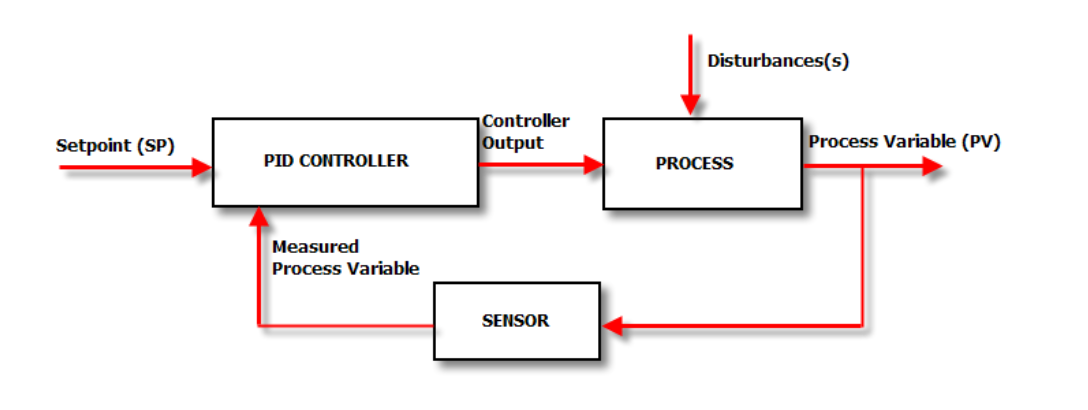

The new equation is given by:


$$Y\left(s\right)=\frac{C\left(s\right)G\left(s\right)}{1+C\left(s\right)G\left(s\right)H\left(s\right)}$$


Where Y is the output, G is the original plant, H is the sensor and C is the controller. 

#### The PID controller Transfer Function

Modeling the controller into MatLab:

syms Kp Ki Kd 
C = Kp + Ki/s + Kd*s

$$C = \mathrm{Kp}+\mathrm{Kd}\,s+\frac{\mathrm{Ki}}{s}$$

The new transfer function is:

Ysym = vpa(combine(simplifyFraction((C*G)/(1+C*G*H))),4)

$$Ysym = \frac{2.0\,\left(1.0e+31\,s+1.0e+34\right)\,\left(5.755e+32\,s+8.87e+31\right)\,\left(\mathrm{Kd}\,s^{2}+\mathrm{Kp}\,s+\mathrm{Ki}\right)}{1.774e+66\,\mathrm{Ki}+1.151e+67\,\mathrm{Ki}\,s+1.774e+66\,\mathrm{Kp}\,s+1.774e+66\,\mathrm{Kd}\,s^{2}+1.151e+67\,\mathrm{Kd}\,s^{3}+1.151e+67\,\mathrm{Kp}\,s^{2}+9.21e+66\,s^{2}+7.399e+66\,s^{3}+1.001e+67\,s^{4}+1.0e+64\,s^{5}}$$

#### Adding Pole Placement

This objective of pole placement is to know which poles would give the ideal result and perform reverse engineering to implement it into the system. If the desired poles are known, the desired characteristic polynomial can be written. the current polynomial and desired polynomial can be compared to find the values for the variables K, a, and b that will yield the desired result. 

As shown, the final equation will have 5 poles.

If the following poles are desired:

desiredPoles = [-250 -225 -200 -175 -150]

desiredPoles =   -250  -225  -200  -175  -150


desiredPoly = poly(desiredPoles);

That would mean that the desired polynomial would be:

DesiredPolynomial = poly2sym(desiredPoly,s)

$$DesiredPolynomial = s^{5}+1000\,s^{4}+396875\,s^{3}+78125000\,s^{2}+7626562500\,s+295312500000$$

The current polynomial is:

[~,den2] = numden(Ysym);
aux1 = vpa(den2,4);
aux2 = vpa(aux1/(1*10^31),4)

$$aux2 = 177.4\,\mathrm{Ki}+1151.0\,\mathrm{Ki}\,s+177.4\,\mathrm{Kp}\,s+177.4\,\mathrm{Kd}\,s^{2}+1151.0\,\mathrm{Kd}\,s^{3}+1151.0\,\mathrm{Kp}\,s^{2}+921.0\,s^{2}+739.9\,s^{3}+1001.0\,s^{4}+1.0\,s^{5}$$

Matching coefficients:


$$739\ldotp 9+1151K_d =396875$$



$$921+1151K_p +177\ldotp 4K_d =78125000$$



$$1151K_i +177\ldotp 4K_p =7626562500$$


eqn3 = (739.9 + 1151*Kd) == 396875;

Solving for Kd, Kp, and Ki:

Kd = vpa(solve(eqn3),4)

$$Kd = 344.2$$

eqn4 = (921 + 1151*Kp + 177.4*Kd) == 78125000;
Kp = vpa(solve(eqn4),4)

$$Kp = 67820.0$$

eqn5 =(1151*Ki+177*Kp) == 7626562500;
Ki = vpa(solve(eqn5),4)

$$Ki = 6.616e+6$$

So our controller final setup:

%Ki = 720/(177.4*10^31)
C = Kp + Ki/s + Kd*s;
C = vpa(C,4)

$$C = 344.2\,s+\frac{6.616e+6}{s}+67820.0$$

The new transfer function is:

Ysym = vpa(simplifyFraction((C*G)/(1+C*G*H)),4);
[num2, den2] = numden(Ysym);
Y= tf(sym2poly(num2),sym2poly(den2))

Y =
 
       3.961e33 s^4 + 4.743e36 s^3 + 8.575e38 s^2 + 7.628e40 s + 1.174e40
  -----------------------------------------------------------------------------
  1e31 s^5 + 1.001e34 s^4 + 3.969e36 s^3 + 7.813e38 s^2 + 7.627e40 s + 1.174e40
 
Continuous-time transfer function.
Model Properties


The roots of this system are:

roots(sym2poly(den2))

ans = 1.0e+02 *

  -3.6225 + 1.1176i
  -3.6225 - 1.1176i
  -1.3804 + 1.8420i
  -1.3804 - 1.8420i
  -0.0015 + 0.0000i


Step response:

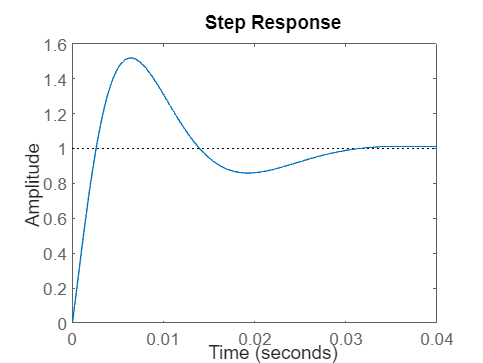

step(Y)

stepinfo(Y)

ans = struct with fields:
         RiseTime: 0.0020
    TransientTime: 0.0291
     SettlingTime: 0.0291
      SettlingMin: 0.8593
      SettlingMax: 1.5188
        Overshoot: 51.8756
       Undershoot: 0
             Peak: 1.5188
         PeakTime: 0.0064


Note: Why were these specific roots chosen? 

Examining the shape of the polynomial that will be managed with Kp, Ki & Kd: $\begin{array}{l}
s^5 +as^4 +bK_1 s^3 +cK_2 s^2 +dK_3 s+eK_4 \\
\textrm{With}\;a,b,c,d\;\textrm{and}\;e\;\textrm{as}\;\textrm{some}\;\textrm{real}\;\textrm{constants}\;\textrm{obtained}\;\textrm{by}\;\textrm{the}\;\textrm{shape}\;\textrm{and}\;\textrm{values}\;\textrm{of}\;\textrm{our}\;\textrm{plant},\textrm{sensor}\;\textrm{and}\;\textrm{controler}\ldotp \\
\textrm{And}\;K_i \;\textrm{as}\;\textrm{some}\;\textrm{different}\;\textrm{mix}\;\textrm{of}\;\textrm{coefficients}\;\textrm{of}\;\textrm{the}\;\textrm{proportional},\textrm{integral}\;\textrm{and}\;\textrm{derivative}\;\textrm{which}\;\textrm{we}\;\textrm{will}\;\textrm{obtain}\;\textrm{to}\;\textrm{match}\;\textrm{our}\;\textrm{desired}\;\textrm{shape}\;\textrm{because}\;\textrm{of}\;\textrm{the}\;\textrm{pole}\;\textrm{placement}\ldotp 
\end{array}$

The problem is that the value of "a" cannot be changed by modifying the controller's coefficients. The only solution is to match the* s*4 coefficient of the desired polynomial with the current polynomial. The natural coefficient of the *s*4 term is about 1000. The roots were picked so the polynomial of those roots would match this, no change K for the other *s* terms is needed. There 4 equations and 3 variables, so one of them will not be satisfied. Therefore, the desired polynomial will not be obtained, and complex results are likely. This would mean that steady state and settling time will be satisfied, but not overshoot. 

### Evaluating different values as  K's

syms s

%Original System
G = vpa((1.151*s + 0.1774)/(s^3 + 0.739*s^2 + 0.921*s),4);
[num1, den1] = numden(G);

%Feedback System
tau = 0.001;
H = vpa(1/(tau*s+1),4);
Ysym2 = vpa(simplify(G/(1+G*H)),5);
[num2, den2] = numden(Ysym2);


#### Sensibility for the Proportional Kp

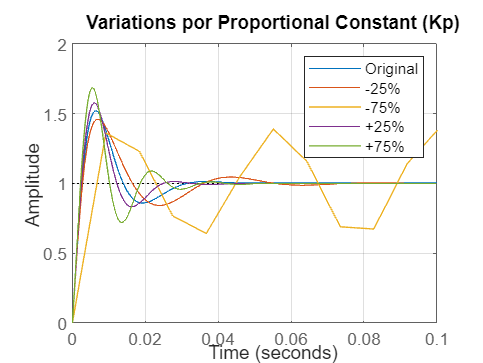

%Functional
Kp = 67820;
Ki = 6615602.1034566658287972790179653;
Kd = 344.2;
C = Kp + Ki/s + Kd*s;
Ysym3 = vpa(simplifyFraction((C*G)/(1+C*G*H)),4);
[num3, den3] = numden(Ysym3);
Y1 = tf(sym2poly(num3),sym2poly(den3));

%Little lower
Kp = 67820*0.75;
C = Kp + Ki/s + Kd*s;
Ysym3 = vpa(simplifyFraction((C*G)/(1+C*G*H)),4);
[num3, den3] = numden(Ysym3);
Y2 = tf(sym2poly(num3),sym2poly(den3));

%Lot lower
Kp = 67820*0.25;
C = Kp + Ki/s + Kd*s;
Ysym3 = vpa(simplifyFraction((C*G)/(1+C*G*H)),4);
[num3, den3] = numden(Ysym3);
Y3 = tf(sym2poly(num3),sym2poly(den3));

%Little Higher
Kp = 67820*1.25;
C = Kp + Ki/s + Kd*s;
Ysym3 = vpa(simplifyFraction((C*G)/(1+C*G*H)),4);
[num3, den3] = numden(Ysym3);
Y4 = tf(sym2poly(num3),sym2poly(den3));

%Lot Higher
Kp = 67820*1.75;
C = Kp + Ki/s + Kd*s;
Ysym3 = vpa(simplifyFraction((C*G)/(1+C*G*H)),4);
[num3, den3] = numden(Ysym3);
Y5 = tf(sym2poly(num3),sym2poly(den3));

step(Y1)
hold on
step(Y2)
step(Y3)
step(Y4)
step(Y5)
axis([0 .1 0 2])
grid on
title("Variations por Proportional Constant (Kp)")
legend("Original","-25%","-75%", "+25%","+75%")
hold off

#### Sensibility for the Derivative  Kd

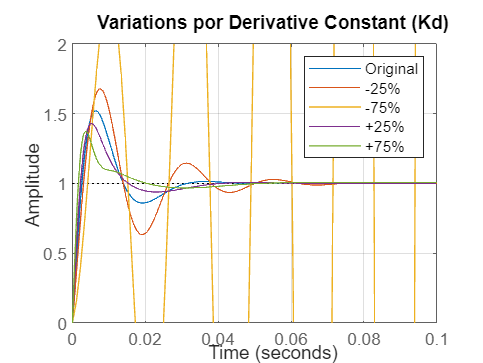

%Functional
Kp = 67820;
Ki = 6615602.1034566658287972790179653;
Kd = 344.2;
C = Kp + Ki/s + Kd*s;
Ysym3 = vpa(simplifyFraction((C*G)/(1+C*G*H)),4);
[num3, den3] = numden(Ysym3);
Y1 = tf(sym2poly(num3),sym2poly(den3));

%Little lower
Kd = 344.2*0.75;
C = Kp + Ki/s + Kd*s;
Ysym3 = vpa(simplifyFraction((C*G)/(1+C*G*H)),4);
[num3, den3] = numden(Ysym3);
Y2 = tf(sym2poly(num3),sym2poly(den3));

%Lot lower
Kd = 344.2*0.25;
C = Kp + Ki/s + Kd*s;
Ysym3 = vpa(simplifyFraction((C*G)/(1+C*G*H)),4);
[num3, den3] = numden(Ysym3);
Y3 = tf(sym2poly(num3),sym2poly(den3));

%Little Higher
Kd = 344.2*1.25;
C = Kp + Ki/s + Kd*s;
Ysym3 = vpa(simplifyFraction((C*G)/(1+C*G*H)),4);
[num3, den3] = numden(Ysym3);
Y4 = tf(sym2poly(num3),sym2poly(den3));

%Lot Higher
Kd = 344.2*1.75;
C = Kp + Ki/s + Kd*s;
Ysym3 = vpa(simplifyFraction((C*G)/(1+C*G*H)),4);
[num3, den3] = numden(Ysym3);
Y5 = tf(sym2poly(num3),sym2poly(den3));

step(Y1)
hold on
step(Y2)
step(Y3)
step(Y4)
step(Y5)
axis([0 .1 0 2])
grid on
title("Variations por Derivative Constant (Kd)")
legend("Original","-25%","-75%", "+25%","+75%")
hold off

#### Sensibility for the Integral Ki

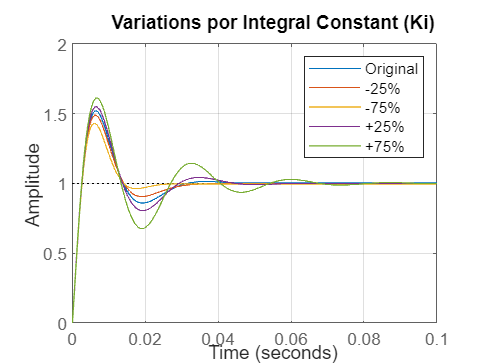

%Functional
Kp = 67820;
Ki = 6615602.1034566658287972790179653;
Kd = 344.2;
C = Kp + Ki/s + Kd*s;
Ysym3 = vpa(simplifyFraction((C*G)/(1+C*G*H)),4);
[num3, den3] = numden(Ysym3);
Y1 = tf(sym2poly(num3),sym2poly(den3));

%Little lower
Ki = 6615602.1034566658287972790179653*0.75;
C = Kp + Ki/s + Kd*s;
Ysym3 = vpa(simplifyFraction((C*G)/(1+C*G*H)),4);
[num3, den3] = numden(Ysym3);
Y2 = tf(sym2poly(num3),sym2poly(den3));

%Lot lower
Ki = 6615602.1034566658287972790179653*0.25;
C = Kp + Ki/s + Kd*s;
Ysym3 = vpa(simplifyFraction((C*G)/(1+C*G*H)),4);
[num3, den3] = numden(Ysym3);
Y3 = tf(sym2poly(num3),sym2poly(den3));

%Little Higher
Ki = 6615602.1034566658287972790179653*1.25;
C = Kp + Ki/s + Kd*s;
Ysym3 = vpa(simplifyFraction((C*G)/(1+C*G*H)),4);
[num3, den3] = numden(Ysym3);
Y4 = tf(sym2poly(num3),sym2poly(den3));

%Lot Higher
Ki = 6615602.1034566658287972790179653*1.75;
C = Kp + Ki/s + Kd*s;
Ysym3 = vpa(simplifyFraction((C*G)/(1+C*G*H)),4);
[num3, den3] = numden(Ysym3);
Y5 = tf(sym2poly(num3),sym2poly(den3));

step(Y1)
hold on
step(Y2)
step(Y3)
step(Y4)
step(Y5)
axis([0 .1 0 2])
grid on
title("Variations por Integral Constant (Ki)")
legend("Original","-25%","-75%", "+25%","+75%")
hold off

This analysis helps us realize that the configuration obtained from pole placement is the best we will possible get.

### The results so far

Step response for different systems:

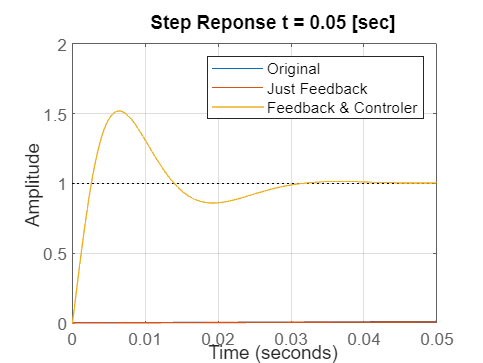

syms s

%Original System
G = vpa((1.151*s + 0.1774)/(s^3 + 0.739*s^2 + 0.921*s),4);
[num1, den1] = numden(G);
Y1= tf(sym2poly(num1),sym2poly(den1));


%Feedback System
tau = 0.001;
H = vpa(1/(tau*s+1),4);
Ysym2 = vpa(simplify(G/(1+G*H)),5);
[num2, den2] = numden(Ysym2);
Y2 = tf(sym2poly(num2),sym2poly(den2));

%Controler System
Kp = 67820;
Ki = 6615602.1034566658287972790179653;
Kd = 344.2;
C = Kp + Ki/s + Kd*s;
Ysym3 = vpa(simplifyFraction((C*G)/(1+C*G*H)),4);
[num3, den3] = numden(Ysym3);
Y3 = tf(sym2poly(num3),sym2poly(den3));

step(Y1)
hold on
step(Y2)
step(Y3)
axis([0 0.05 0 2])
grid on
hold off
title("Step Reponse t = 0.05 [sec]")
legend("Original", "Just Feedback", "Feedback & Controler")

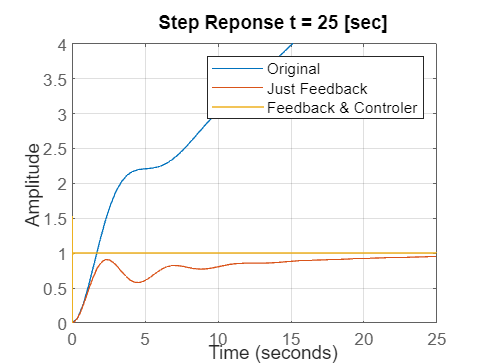


step(Y1)
hold on
step(Y2)
step(Y3)
axis([0 25 0 4])
grid on
hold off
title("Step Reponse t = 25 [sec]")
legend("Original", "Just Feedback", "Feedback & Controler")

The yellow line has a very small settling time. This is a lot of improvement when compared to the red and blue curves. 

stepinfo(Y3)

ans = struct with fields:
         RiseTime: 0.0020
    TransientTime: 0.0291
     SettlingTime: 0.0291
      SettlingMin: 0.8594
      SettlingMax: 1.5187
        Overshoot: 51.8702
       Undershoot: 0
             Peak: 1.5187
         PeakTime: 0.0064


All requirements are met from the system except for the overshoot requirement. The very small settling time and no steady state error somewhat compensate for the extra overshoot. However, extra measures will be taken to test if overshoot can be mitigated.

### Root Locus Plots

syms s

%Original System
G = vpa((1.151*s + 0.1774)/(s^3 + 0.739*s^2 + 0.921*s),4);
[num1, den1] = numden(G);
Y1= tf(sym2poly(num1),sym2poly(den1));


%Feedback System
tau = 0.001;
H = vpa(1/(tau*s+1),4);
Ysym2 = vpa(simplify(G/(1+G*H)),5);
[num2, den2] = numden(Ysym2);
Y2 = tf(sym2poly(num2),sym2poly(den2));

%Controler System
Kp = 67820;
Ki = 6615602.1034566658287972790179653;
Kd = 344.2;
C = Kp + Ki/s + Kd*s;
Ysym3 = vpa(simplifyFraction((C*G)/(1+C*G*H)),4);
[num3, den3] = numden(Ysym3);
Y3 = tf(sym2poly(num3),sym2poly(den3));


The system is not fully operational because the overshoot requirement has not been met.

Analyzing the roots of the system, complex numbers are present. 

roots(sym2poly(den3))

ans = 1.0e+02 *

  -3.6227 + 1.1208i
  -3.6227 - 1.1208i
  -1.3802 + 1.8412i
  -1.3802 - 1.8412i
  -0.0015 + 0.0000i


Plotting the root locus it is evident that changing values of K's cannot have them exist exclusively in the real axis. Therefore, this is the best possible result. 

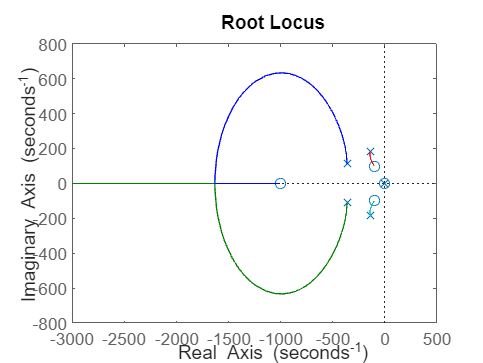

rlocus(Y3)

## Analysis of Frecuency Reponse

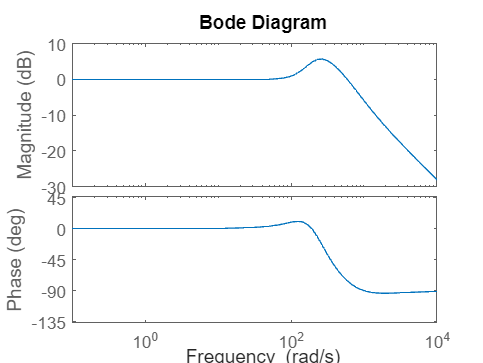

syms s

%Original System
G = vpa((1.151*s + 0.1774)/(s^3 + 0.739*s^2 + 0.921*s),4);
[num1, den1] = numden(G);
Y1= tf(sym2poly(num1),sym2poly(den1));


%Feedback System
tau = 0.001;
H = vpa(1/(tau*s+1),4);
Ysym2 = vpa(simplify(G/(1+G*H)),5);
[num2, den2] = numden(Ysym2);
Y2 = tf(sym2poly(num2),sym2poly(den2));


%Controler System
Kp = 67820;
Ki = 6615602.1034566658287972790179653;
Kd = 344.2;
C = Kp + Ki/s + Kd*s;
Ysym3 = vpa(simplifyFraction((C*G)/(1+C*G*H)),4);
[num3, den3] = numden(Ysym3);
Y3 = tf(sym2poly(num3),sym2poly(den3));
bode(Y3)

This analysis studies how the system would respond to different frequencies. The Bode diagram shows that the system should be fully operational in frequencies from 0.1 to 100 rads/sec. Frequencies greater than this will result in an inconsistent system. Also the phase will start shifting.  

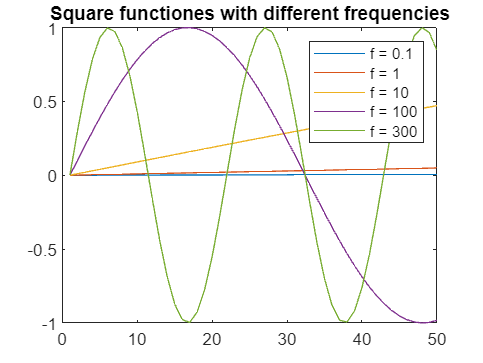

t = [0*pi:0.001:10*pi];
f1 = sin(0.1*t);
f2 = sin(1*t);
f3 = sin(10*t);
f4 = sin(100*t);
f5 = sin(300*t);
plot(f1);
hold on
plot(f2);
plot(f3);
plot(f4);
plot(f5);
hold off
title("Square functiones with different frequencies")
legend("f = 0.1","f = 1","f = 10","f = 100","f = 300")
axis([0,50,-1,1])

Considering multiple inputs, the green line will not work on our system due to the high frequency:

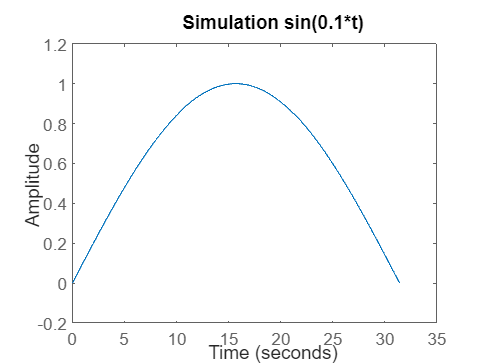

lsim(Y3, f1, t)
title("Simulation sin(0.1*t)")

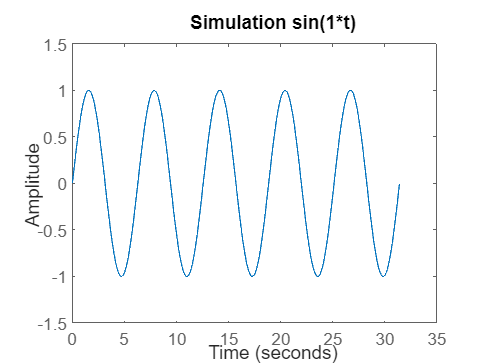

lsim(Y3, f2, t)
title("Simulation sin(1*t)")

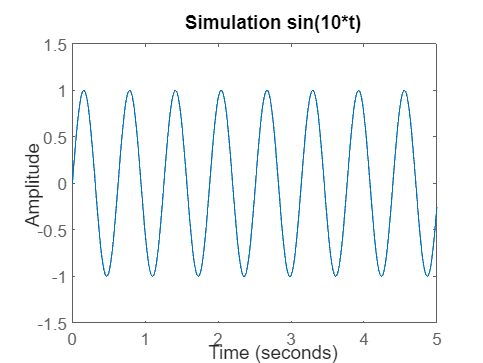


lsim(Y3, f3, t)
title("Simulation sin(10*t)")
axis([0 5 -1.5 1.5])

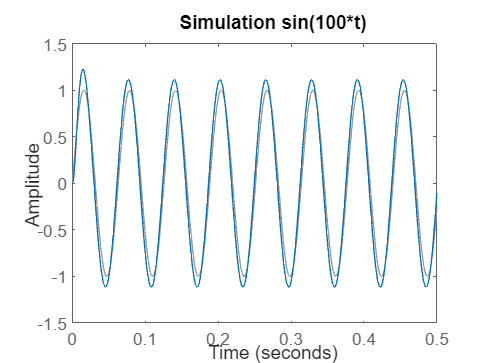

lsim(Y3, f4, t)
title("Simulation sin(100*t)")


axis([0 0.5 -1.5 1.5])

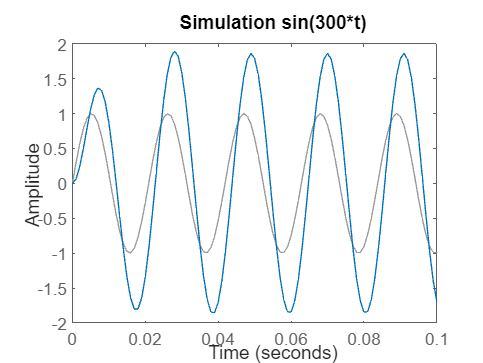

title("Simulation sin(100*t)")


lsim(Y3, f5, t)
axis([0 0.1 -2 2])
title("Simulation sin(300*t)")

As can be seen, all linear simulations didn't distinguish between the input "grey" and the output "blue" until the last two plots. The frequency of 100 rad/sec is starting to get a bit of phase shifting and some unclear magnitude. But when at 300 rad/sec the magnitude and phasing goes terribly bad. 

This confirms the behavior observed on the Bode plot, the operation range for our system goes from frequencies 0.1 to 100 rads/sec. 

## Machine-Learning Controler

Assume a system with perfect feedback. It has a simple input but an unknown disturbance is added to the response. To solve this, a machine learning approach can be taken. For this scenario, a discrete approach can be taken, assuming the input is a mere unit step function. The output should also be a step response but somehow is not. 

For this example, a simple upwards waveform simulates the increase of elevation at the lift of a flight, peak altitude, and then descent for landing. 

t = -10:0.1:50;
x = sin(0.1*t);
plot(t,x)
hold on

a = [1 1];
b = [1 4 4 1];
s = tf('s');
G = (a(1)*s + a(2))/(b(1)*s^3 + b(2)*s^2 + b(3)*s + b(4))

G =
 
          s + 1
  ---------------------
  s^3 + 4 s^2 + 4 s + 1
 
Continuous-time transfer function.
Model Properties


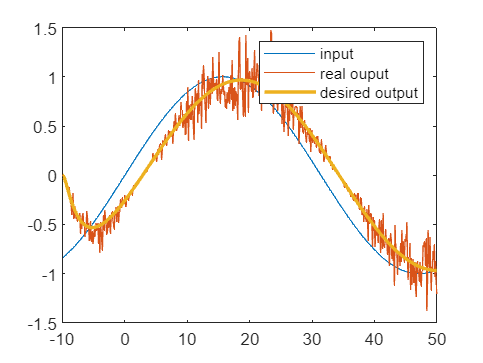




[y, ~] = lsim(G, x, t);



D_noise = normrnd(1, 0.2, [1, length(t)]);

y_noise = y.*transpose(D_noise);

plot(t, y_noise, LineWidth=0.01)
plot(t, y, LineWidth=2)


hold off
legend("input", "real ouput", "desired output", Location="northeast")

As can be seen, noise is present in the real output, but the end desired result output is the step response. Performing linear regression over the output allows for the approximation of the result.

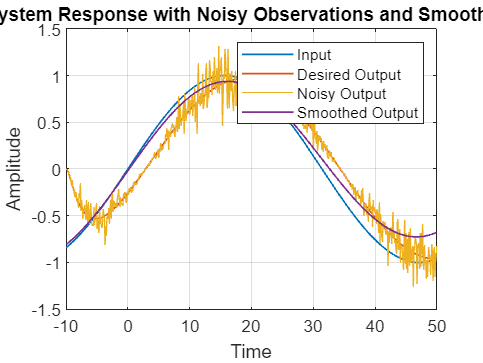

t = -10:0.1:50;

% Create a step input

x = sin(0.1*t);

% Define the system transfer function
a = [1 1];
b = [1 4 4 1];
s = tf('s');
G = (a(1)*s + a(2))/(b(1)*s^3 + b(2)*s^2 + b(3)*s + b(4));

Ts = 0.01;

% Convert the transfer function to discrete-time
G_d = c2d(G, Ts, 'zoh');

% Simulate the ideal response
[y, ~] = lsim(G, x, t);

% Generate noisy observations
D_noise = normrnd(1.0, 0.2, [1, length(t)]);
y_noise = y.*transpose(D_noise);


% Apply linear regression to smooth the noisy output
X = [t', x'];
mdl = fitlm(X, y_noise');

% Predict the smoothed output
y_smoothed = predict(mdl, X);

% Plot the results
figure;
plot(t, x, 'LineWidth', 1, 'DisplayName', 'Input');
hold on;
plot(t, y, 'LineWidth', 1, 'DisplayName', 'Desired Output');
plot(t, y_noise, 'LineWidth', 0.1, 'DisplayName', 'Noisy Output');
plot(t, y_smoothed, 'LineWidth', 1, 'DisplayName', 'Smoothed Output');
hold off;
legend('Location', 'northeast');
title('System Response with Noisy Observations and Smoothing');
xlabel('Time');
ylabel('Amplitude');
grid on;

To conclude, with the machine learning approach, linear regression managed to smooth out the output, dealing with the uncertainty of a noisy channel. 

## Appendices

### First: Variable summary


$$\alpha \;=\textrm{Angle}\;\textrm{of}\;\textrm{at}\textrm{tack}$$



$$q=\textrm{Pitch}\;\textrm{ra}\textrm{te}$$



$$\theta =\textrm{Pitch}\;\textrm{angle}$$



$$\delta \;=\textrm{Elevator}\;\textrm{deflection}\;\textrm{angle}$$



$$\mu =\frac{\rho S\bar{c} }{4m}$$



$$\rho =1\ldotp 125\;\frac{\textrm{kg}}{m^3 }\;=\;\textrm{Density}\;\textrm{of}\;\textrm{air}$$



$$S=124\;m^{2\;} =\;\textrm{Platform}\;\textrm{area}\;\textrm{of}\;\textrm{the}\;\textrm{wing}$$



$$\bar{c} =3\ldotp 4\;m=\;\textrm{Average}\;\textrm{cord}\;\textrm{length}$$



$$m=79,000-41,145\;kg=\;\textrm{Mass}\;\textrm{of}\;\textrm{the}\;\textrm{aircraft}$$



$$\Omega =\frac{2U}{\bar{c} }$$



$$U=450\;\textrm{knots}=\;\textrm{Equilibrium}\;\textrm{flight}\;\textrm{speed}\ldotp$$



$$C_T =0\ldotp 3-0\ldotp 5=\;\textrm{Coefficient}\;\textrm{of}\;\textrm{thrust}$$



$$C_D =0\ldotp 02-0\ldotp 04=\;\textrm{Coefficient}\;\textrm{of}\;\textrm{drag}$$



$$C_L =0\ldotp 5-1\ldotp 2=\;\textrm{Coefficient}\;\textrm{of}\;\textrm{lift}$$



$$C_W =1=\;\textrm{Coefficient}\;\textrm{of}\;\textrm{weight}$$



$$C_M =0\ldotp 01=\;\textrm{Coefficient}\;\textrm{of}\;\textrm{pitch}\;\textrm{moment}$$



$$\gamma =\textrm{Flight}\;\textrm{path}\;\textrm{angle}$$



$$\sigma =\frac{1}{1+\mu C_L }=\textrm{constant}$$



$$i_{\textrm{yy}} =\textrm{Normalized}\;\textrm{moment}\;\textrm{of}\;\textrm{inertia}$$



$$\eta =\mu \sigma C_M =\textrm{constant}$$
 

### Second: Algebra

#### From equations of motion to Laplace Transform 

We begin with our equations of motion

syms alpha(t) q(t) delta(t) theta(t)
eqn1 = diff(alpha(t),1) ==-0.313*alpha + 56.7*q+0.232*delta

$$eqn1(t) = \frac{\partial }{\partial t}\alpha \left(t\right)=\frac{29\,\delta \left(t\right)}{125}-\frac{313\,\alpha \left(t\right)}{1000}+\frac{567\,q\left(t\right)}{10}$$

eqn2 = diff(q(t),1) == -0.0139*alpha - 0.426*q + 0.0203*delta

$$eqn2(t) = \frac{\partial }{\partial t}q\left(t\right)=\frac{203\,\delta \left(t\right)}{10000}-\frac{139\,\alpha \left(t\right)}{10000}-\frac{213\,q\left(t\right)}{500}$$

eqn3 = diff(theta(t),1)==56.7*q

$$eqn3(t) = \frac{\partial }{\partial t}\theta \left(t\right)=\frac{567\,q\left(t\right)}{10}$$

Then we do Laplace Transform and set initials conditions to zero

syms s
EQN1_AUX = laplace(eqn1,s);
EQN1 = subs(EQN1_AUX,alpha(0),0);
EQN2_AUX = laplace(eqn2,s);
EQN2 = subs(EQN2_AUX,q(0),0);
EQN3_AUX = laplace(eqn3,s);
EQN3 = subs(EQN3_AUX, theta(0),0);

Because MATLAB does not support solving for laplace-type variables, we are going to substitute our own variables.

syms Q A D T
EQN1 = subs(EQN1, laplace(q(t),t,s), Q);
EQN1 = subs(EQN1, laplace(alpha(t),t,s), A);
EQN1 = subs(EQN1, laplace(delta(t),t,s), D);
EQN1 = subs(EQN1, laplace(theta(t),t,s), T)

$$EQN1 = A\,s=\frac{29\,\text{D}}{125}-\frac{313\,A}{1000}+\frac{567\,Q}{10}$$

EQN2 = subs(EQN2, laplace(q(t),t,s), Q);
EQN2 = subs(EQN2, laplace(alpha(t),t,s), A);
EQN2 = subs(EQN2, laplace(theta(t),t,s), T);
EQN2 = subs(EQN2, laplace(delta(t),t,s), D)

$$EQN2 = Q\,s=\frac{203\,\text{D}}{10000}-\frac{139\,A}{10000}-\frac{213\,Q}{500}$$

EQN3 = subs(EQN3, laplace(q(t),t,s), Q);
EQN3 = subs(EQN3, laplace(theta(t),t,s), T)

$$EQN3 = T\,s=\frac{567\,Q}{10}$$

#### From Laplace Transform to Transfer Function

Now we do some algebraic manipulation to get to the Transfer Function with output us Theta and Input Delta.


$$G\left(s\right)=\frac{\Theta \left(s\right)}{\Delta \left(s\right)}$$


We solve Eq. 2 for A and name it Eq.4

EQN4 = solve(EQN2, A) 

$$EQN4 = \frac{203\,\text{D}}{139}-\frac{4260\,Q}{139}-\frac{10000\,Q\,s}{139}$$

We substitute Eq. 4 as A in Eq.1 and name it Eq. 5

EQN5 = subs(EQN1,A,EQN4)

$$EQN5 = -s\,\left(\frac{4260\,Q}{139}-\frac{203\,\text{D}}{139}+\frac{10000\,Q\,s}{139}\right)=\frac{230367\,Q}{3475}-\frac{31291\,\text{D}}{139000}+\frac{3130\,Q\,s}{139}$$

We solve Eq. 5 for Q and name it Eq. 6

EQN6 = solve(EQN5,Q)

$$EQN6 = \frac{31291\,\text{D}+203000\,\text{D}\,s}{10000000\,s^{2}+7390000\,s+9214680}$$

We substitute Eq. 6 as Q in Eq. 6 and name it Eq. 7

EQN7 = subs(EQN3, Q, EQN6)

$$EQN7 = T\,s=\frac{567\,\left(31291\,\text{D}+203000\,\text{D}\,s\right)}{10\,\left(10000000\,s^{2}+7390000\,s+9214680\right)}$$

We solve Eq. 7 for T and name it Eq.8

EQN8 = solve(EQN7, T)

$$EQN8 = \frac{567\,\left(31291\,\text{D}+203000\,\text{D}\,s\right)}{10\,s\,\left(10000000\,s^{2}+7390000\,s+9214680\right)}$$

We divide Eq. 8 over D to get the transfer function and to simplify the answer.

G = simplify(EQN8/D)

$$G = \frac{115101000\,s+17741997}{400\,s\,\left(250000\,s^{2}+184750\,s+230367\right)}$$

Now we obtain our transfer function:

G = vpa(simplify(G), 5)

$$G = \frac{0.0025\,\left(1.151e+8\,s+1.7742e+7\right)}{s\,\left(250000.0\,s^{2}+184750.0\,s+230370.0\right)}$$

[symNum, symDen] = numden(G);
num = sym2poly(symNum);
den = sym2poly(symDen);
G = tf(num,den)

G =
 
        2.878e05 s + 4.435e04
  ----------------------------------
  250000 s^3 + 184750 s^2 + 230367 s
 
Continuous-time transfer function.
Model Properties


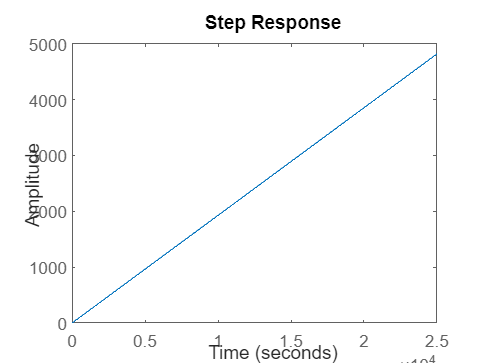

step(G)